defaultDir = 'M:\Bergles Lab Data\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure 2 - ISCs']);

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 25; %threshold in pA
conditions = {'Baseline','MRS','MRS+SP','Washout'};
conditionTimes = [0 300; 540 840; 960 1260; 2100 2400];

%%dir 
dname = '.\Data\WT_MRS_PPADS_PT';
folderlist = dir(dname);
folderlist = folderlist(3:end);
analyze = [0 0 1 0];

if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end

for i = 1:size(folderlist,1)
    if analyze(1)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_p.abf']);
        [d,time] = loadPclampData(fileList{1});
        cellS(i).bl_R = calcRm(d,time,pulse,pulseTime);
    end
    
    if analyze(2)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_gfi.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
        cellS(i).Vm = mean(d - out);
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([dname '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        % figure; plot(time,out);
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        
        if exist('stats')
            clear 'stats'; 
        end
        for j = 1:size(conditionTimes,1)
            stats(j).condition = conditions{j};
            stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                     out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
            stats(j).integral = cumFunc(end);
            
        end
        
        cellS(i).stats = stats;
        tempCell = cellS(i);
        [d,f,ext] = fileparts(fileList{1});
        save([d '\' f '_stats.mat'],'tempCell')
    end
   
    if analyze(4)
        fileList = loadFileList([dname '\' folderlist(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).post_R = calcRm(d,time,pulse,pulseTime);
        end
    end
    
    
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_MRS_PPADS_PT\170727_Cell1\18727002_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 92 MB
opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_MRS_PPADS_PT\170727_Cell2\18727023_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 92 MB
opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_MRS_PPADS_PT\170727_Cell3\18727027_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 92 MB
opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_MRS_P

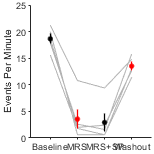

pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

dim = [1.6 1.6];
compare4P(pkstatBlock(:,1),pkstatBlock(:,2),pkstatBlock(:,3),pkstatBlock(:,4),conditions,'Events Per Minute',dim,[5 12]);
ylim([0 25]);
yticks(0:5:25);
export_fig('.\EPS Panels\MRSfreq.eps');

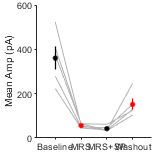


compare4P(ampstatBlock(:,1),ampstatBlock(:,2),ampstatBlock(:,3),ampstatBlock(:,4),conditions,'Mean Amp (pA)',dim,[5 12]);
ylim([0 600]);
yticks(0:200:600);
export_fig('.\EPS Panels\MRSamp.eps');

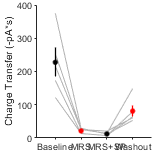


compare4P(intstatBlock(:,1),intstatBlock(:,2),intstatBlock(:,3),intstatBlock(:,4),conditions,'Charge Transfer (-pA*s)',dim,[5 12]);
ylim([0 400]);
yticks(0:100:400);
export_fig('.\EPS Panels\MRSint.eps');

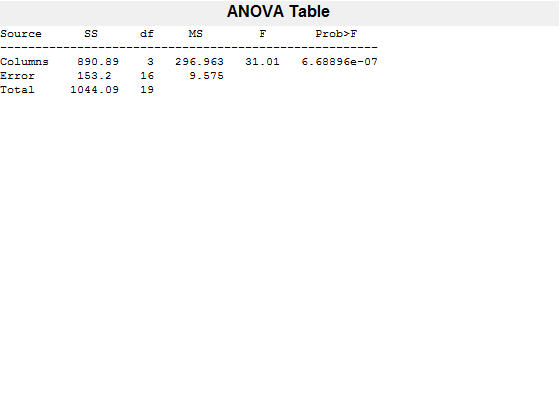

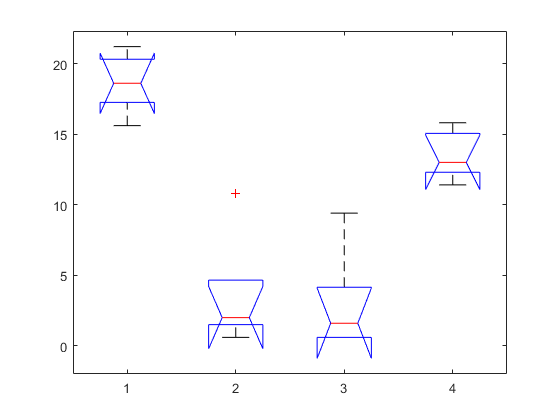

[p,~,stats] = anova1(pkstatBlock);

[c] = multcompare(stats,'display','off')

c =     1.0000    2.0000    9.4809   15.0800   20.6791    0.0000
    1.0000    3.0000   10.1209   15.7200   21.3191    0.0000
    1.0000    4.0000   -0.4791    5.1200   10.7191    0.0793
    2.0000    3.0000   -4.9591    0.6400    6.2391    0.9875
    2.0000    4.0000  -15.5591   -9.9600   -4.3609    0.0006
    3.0000    4.0000  -16.1991  -10.6000   -5.0009    0.0003


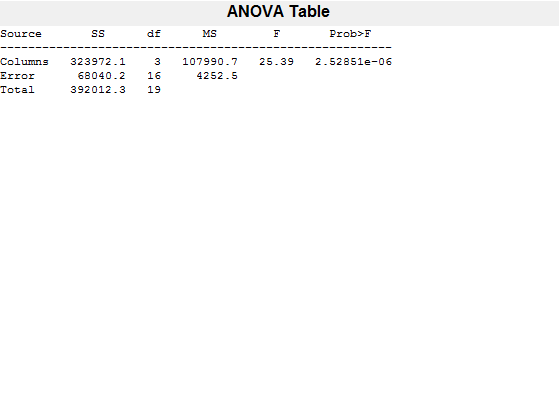

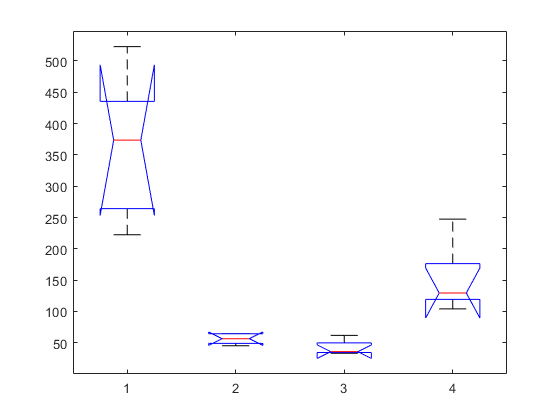


[p,~,stats] = anova1(ampstatBlock);

[c1] = multcompare(stats,'display','off')

c1 =     1.0000    2.0000  186.6080  304.6057  422.6034    0.0000
    1.0000    3.0000  200.4397  318.4374  436.4351    0.0000
    1.0000    4.0000   91.1661  209.1638  327.1615    0.0006
    2.0000    3.0000 -104.1661   13.8317  131.8294    0.9865
    2.0000    4.0000 -213.4396  -95.4419   22.5558    0.1362
    3.0000    4.0000 -227.2713 -109.2735    8.7242    0.0746


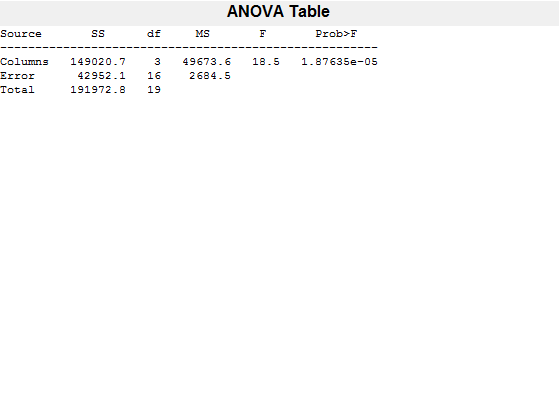

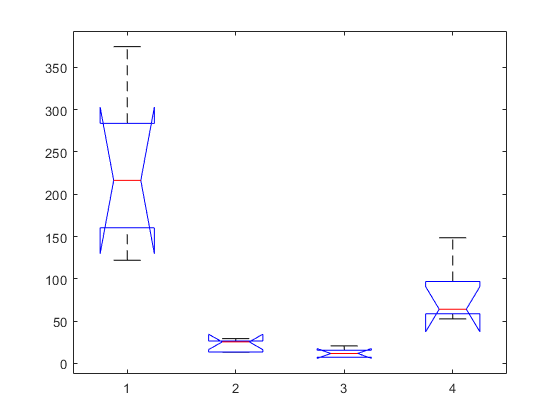


[p,~,stats] = anova1(intstatBlock);

[c2] = multcompare(stats,'display','off')

c2 =     1.0000    2.0000  112.8395  206.5920  300.3446    0.0001
    1.0000    3.0000  122.0370  215.7896  309.5422    0.0000
    1.0000    4.0000   53.0928  146.8454  240.5979    0.0019
    2.0000    3.0000  -84.5550    9.1976  102.9501    0.9920
    2.0000    4.0000 -153.4992  -59.7467   34.0059    0.2989
    3.0000    4.0000 -162.6968  -68.9442   24.8083    0.1939


opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180802_Cell1\18802002_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 92 MB


savename = '18802002_gfv'

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180802_Cell2\18802018_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1327.9 s ~ 22 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 51 MB


savename = '18802018_gfv'

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell2\18823011_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1528.8 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 58 MB


savename = '18823011_gfv'

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell4\18823025_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1505.5 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB


savename = '18823025_gfv'

opening M:\Projects and Analysis\Papers\P2ry1\Figure 2 - ISCs\Data\KO_MRS_PPADS_PT\180827_Cell2\18827018_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1501.1 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB


savename = '18827018_gfv'

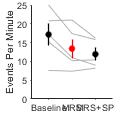

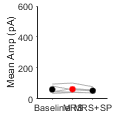

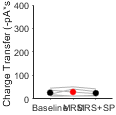

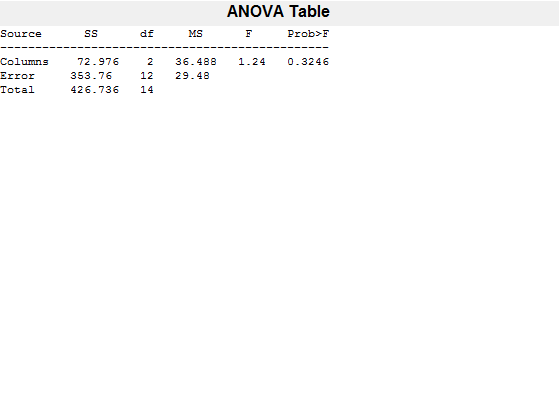

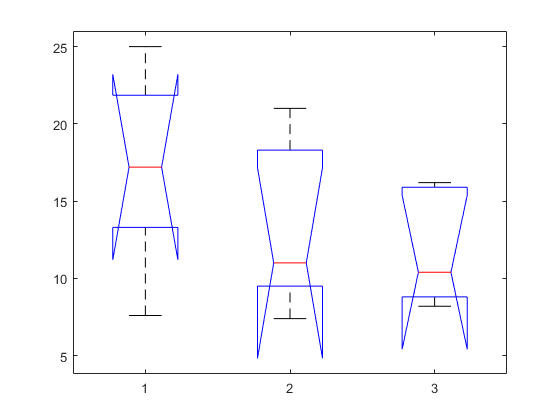

c =     1.0000    2.0000   -5.4013    3.7600   12.9213    0.5350
    1.0000    3.0000   -3.9213    5.2400   14.4013    0.3140
    2.0000    3.0000   -7.6813    1.4800   10.6413    0.9035


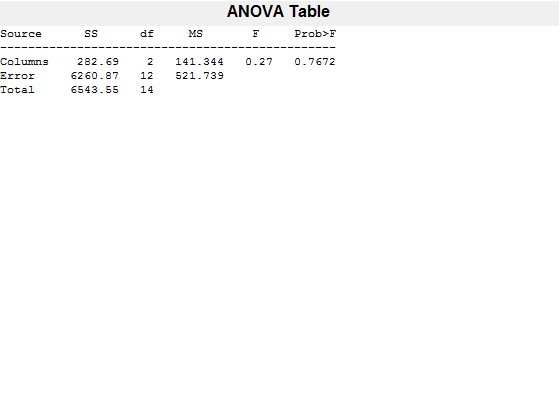

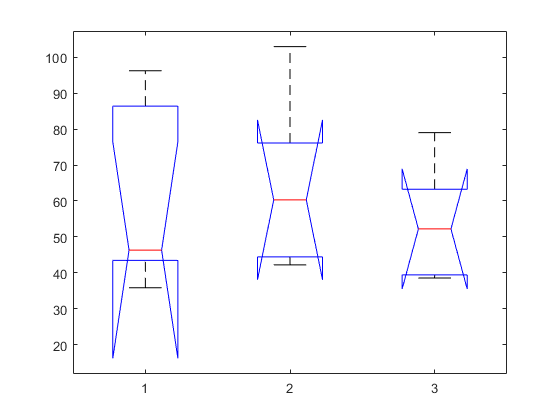

c1 =     1.0000    2.0000  -40.6152   -2.0745   36.4663    0.9887
    1.0000    3.0000  -30.5459    7.9949   46.5356    0.8467
    2.0000    3.0000  -28.4714   10.0693   48.6101    0.7697


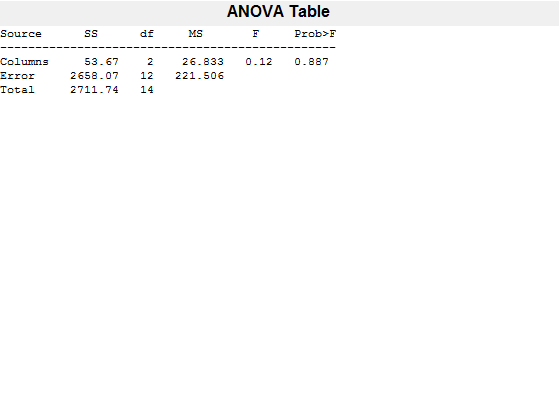

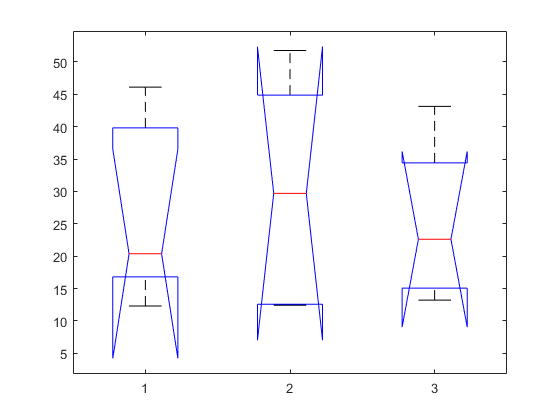

c2 =     1.0000    2.0000  -27.9702   -2.8579   22.2543    0.9507
    1.0000    3.0000  -23.3831    1.7292   26.8415    0.9816
    2.0000    3.0000  -20.5252    4.5871   29.6994    0.8786


opening .\Data\KO_MRS_PPADS_PT\180823_Cell4\18823025_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1505.5 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB